# Free bar implementation

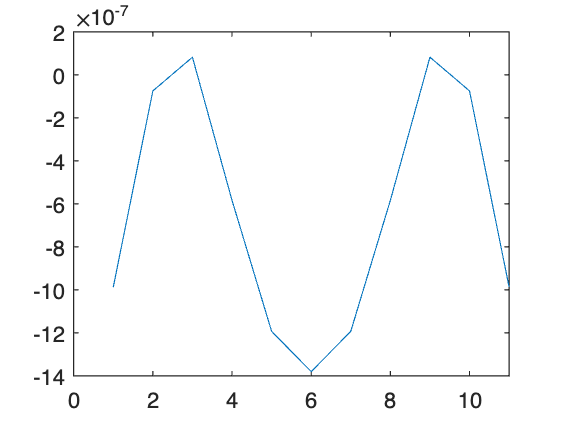

% Simon Andersen
% sand22@student.aau.dk

clc;
% marimba params
L = 0.473;                      % length
rho = 880;                      % material density (rosewood)
E = 2.45387e+13;                % young's modulus (rosewood)
I = 4.91e-14;                   % moment of inertia
A = 7.85e-07;                   % cross-sectional area

% damping params
sigma0 = 0.02;                  % first damping term
sigma1 = 0.0697;                % second damping term

% system params
fs = 44100;                     % sample rate
f0 = 440;                       % fundamental frequency
seconds = 1;                    % length of audio
lengthSound = fs * seconds;     % samples for calculation

kappa = sqrt((E*I)/(rho*A));    % stability condition

k = 1/fs;                       % temporal step size
c = 2 * L * f0;                 % wave speed
h = sqrt(2 * kappa * k);        % spatial time step 
N = floor(L/h);                 % the actual time step that we use 
h = L/N;                        % recalculation of h

% array initialization
uNext = zeros(N+1, 1);          % next time step
u = zeros(N+1, 1);              % current time step
uPrev = zeros(N+1, 1);          % previous time step

% excitation
u(3:9) = hann(7);               % applying hanning window as excitation
uPrev = u;                      % copy value for calculation

% output initialization
out = zeros(lengthSound, 1);    % waveform
outIx = round((N+1)/3);         % listening point

% Time integration loop
for j = 1:lengthSound
    % Compute displacement for the free bar 
    for l = 1:N+1
        if l == 1
            uLeft_1 = 2 * u(1) - u(2);                      % u left virtual grid point      : - 1
            uLeft_2 = u(3) - 2 * u(2) + 2 * uLeft_1;        % u left virtual grid point      : - 2
            uPrevLeft = 2 * uPrev(1) - uPrev(2);            % uPrev left virtual grid point  : - 1
            uNext(l) = (2 * u(l) - uPrev(l)) / (1 + 2 * sigma0 * (k / (rho * A))) + (k^2 / (rho * A)) * (- (E * I/h^4) * (u(l+2) - 4*u(l+1) + 6*u(l) - 4*uLeft_1 + uLeft_2) + (2 * sigma1 / k * h^2) * (u(l+1) - 2 * u(l) + uLeft_1 - uPrev(l + 1) + 2 * uPrev(l) - uPrevLeft));
        elseif l == 2
            uLeft_1 = 2 * u(1) - u(2);                      % u left boundary : - 1
            uNext(l) = (2 * u(l) - uPrev(l)) / (1 + 2 * sigma0 * (k / (rho * A))) + (k^2 / (rho * A)) * (- (E * I/h^4) * (u(l+2) - 4*u(l+1) + 6*u(l) - 4*u(l-1) + uLeft_1) + (2 * sigma1 / k * h^2) * (u(l+1) - 2 * u(l) + u(l-1) - uPrev(l + 1) + 2 * uPrev(l) - uPrev(l - 1)));
        elseif l == N+1
            uRight_1 = 2 * u(N+1) - u(N);                   % u right virtual grid point     : + 1
            uRight_2 = u(N-1) - 2 * u(N) + 2 * uRight_1;    % u right virtual grid point     : + 2
            uPrevRight = 2 * uPrev(N+1) - uPrev(N);         % uPrev right virtual grid point : + 1
            uNext(l) = (2 * u(l) - uPrev(l)) / (1 + 2 * sigma0 * (k / (rho * A))) + (k^2 / (rho * A)) * (- (E * I/h^4) * (uRight_2 - 4*uRight_1 + 6*u(l) - 4*u(l-1) + u(l-2)) + (2 * sigma1 / k * h^2) * (uRight_1 - 2 * u(l) + u(l-1) - uPrevRight + 2 * uPrev(l) - uPrev(l - 1)));
        elseif l == N
            uRight_1 = 2 * u(N+1) - u(N);                   % u right virtual grid point     : + 1
            uNext(l) = (2 * u(l) - uPrev(l)) / (1 + 2 * sigma0 * (k / (rho * A))) + (k^2 / (rho * A)) * (- (E * I/h^4) * (uRight_1 - 4*u(l+1) + 6*u(l) - 4*u(l-1) + u(l-2)) + (2 * sigma1 / k * h^2) * (u(l+1) - 2 * u(l) + u(l-1) - uPrev(l + 1) + 2 * uPrev(l) - uPrev(l - 1)));
        else
            uNext(l) = (2 * u(l) - uPrev(l)) / (1 + 2 * sigma0 * (k / (rho * A))) + (k^2 / (rho * A)) * (- (E * I/h^4) * (u(l+2) - 4*u(l+1) + 6*u(l) - 4*u(l-1) + u(l-2)) + (2 * sigma1 / k * h^2) * (u(l+1) - 2 * u(l) + u(l-1) - uPrev(l + 1) + 2 * uPrev(l) - uPrev(l - 1)));
        end
    end
    
    % Store the output (from the physical domain)
    out(j) = uNext(outIx);
    
    % Update uPrev and u for next time step
    uPrev = u;
    u = uNext;

    % plot(uNext);
    % plot(out);
    % drawnow;
    
end

plot(uNext);

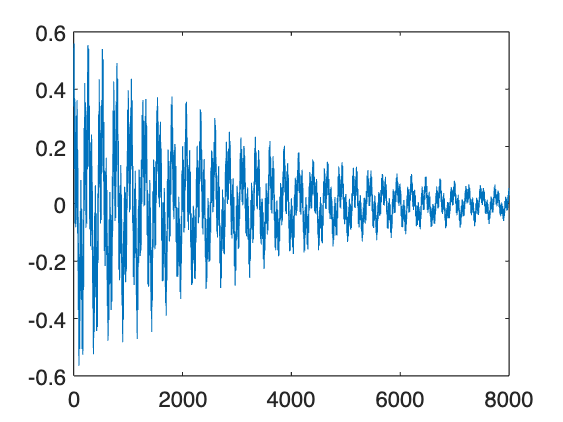

plot(out);
xlim([0 8000]);

% reviewing the audio
soundsc(out, fs);

filename = 'free.wav';

% Export the audio data to a WAV file
audiowrite(filename, out, fs);

% Confirm the file was written
disp(['Audio data has been written to ' filename]);

Audio data has been written to free.wav


% applying lowpass filter on the audio to cut off high frequencies
fc = 1000; % cutoff
order = 4; % order (4 for Butterworth)

% lowpass Butterworth filter
[b, a] = butter(order, fc / (fs / 2), 'low');
filtered_signal = filter(b, a, out);

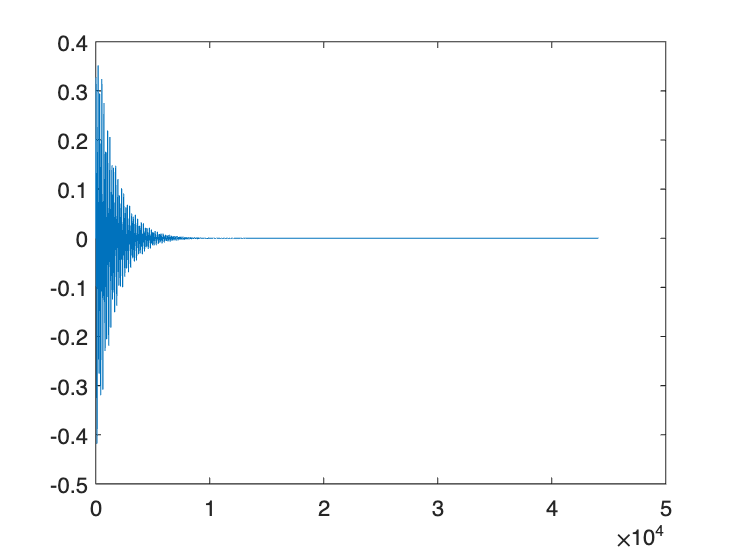

% reviewing filtered signal
plot(filtered_signal);

soundsc(filtered_signal, fs);

filename = 'freeLowpass.wav';

% Export the audio data to a WAV file
audiowrite(filename, filtered_signal, fs);

% Confirm the file was written
disp(['Audio data has been written to ' filename]);

Audio data has been written to freeLowpass.wav
